# Project: Radar Target Generation and Detection

%%Cleanup
%
clear all
clc;

## Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
C = 3e8;
R_max = 200;
R_res = 1;
V_max = 100;

## User Defined Range and Velocity of target

**%TODO** : define the target's initial position and velocity. Note : Velocity remains contant

Vi = 35;  %35 ms/s
Ti = 0;   %2 degrees
Ri = 100; %100 meters

## FMCW Waveform Generation

% *%TODO* :
%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.

B = C / (2 * R_res);
Tchirp = 5.5* (2 * R_max / C);
Slope = B / Tchirp;

%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq

                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

## Signal generation and Moving Target simulation

Running the radar scenario over the time. 

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = Ri + Vi * t(i);
    R = r_t(i);
    Td(i) = (R * 2) / C;
    Tau = Td(i);
    
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2 * pi * ((fc * t(i)) + (Slope * (t(i)^2) / 2)));
    Rx(i) = cos(2 * pi * ((fc * (t(i)-Tau)) + (Slope * ((t(i)-Tau)^2) / 2)));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i) * Rx(i);
    %For testing using another method to calculate Mix signal without simulation of Tx and Rx Path
    Mix_ref(i) = cos(2 * pi * ((2 * fc * Vi/C * t(i)) + (2 * Slope * (R/C) * t(i))));
end

## RANGE MEASUREMENT

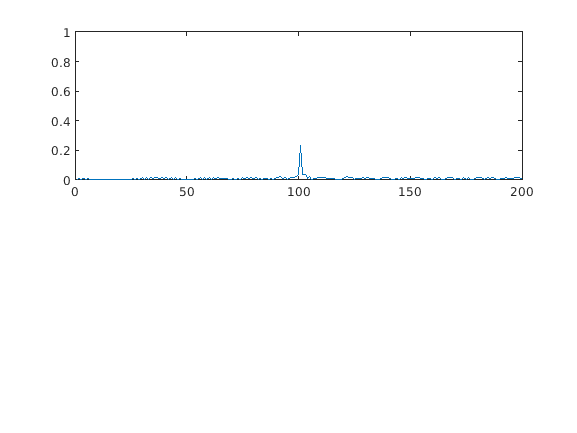

 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
signal = reshape(Mix, [Nr, Nd]);

 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
dim = 1;
L = Nr;
signal_fft = fft(signal,Nr);
signal_fft_norm = signal_fft./Nr;

 % *%TODO* :
% Take the absolute value of FFT output
signal_fft_abs = abs(signal_fft_norm);

 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
signal_fft_abs = signal_fft_abs(1:(Nr/2));

%plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

 % *%TODO* :
 % plot FFT output 
plot(signal_fft_abs);
 
axis ([0 200 0 1]);

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.You will implement CFAR on the generated RDM

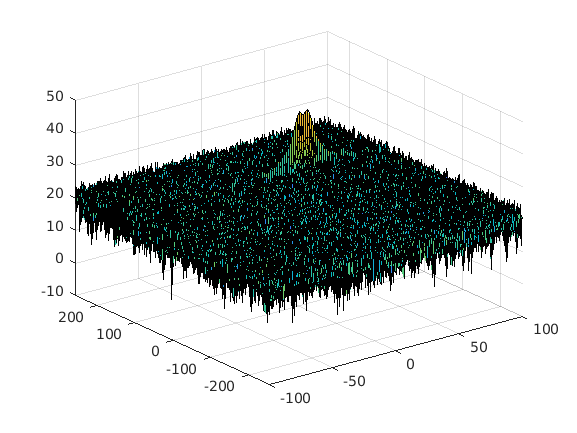

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## CFAR implementation

I added implementation and output inline by opening the file as Matlab live-script

% Slide Window through the complete Range Doppler Map
% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 7; %Training cells on range dim
Td = 3; %Training cells on doppler dim
% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 3; %Guard cells on range dim
Gd = 2; %Guard cells on doppler dim
% *%TODO* :
% offset the threshold by SNR value in dB
offset = 1.47;

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
TGCells_range = (Tr+Gr) * 2;
TGCells_doppler = (Td+Gd) * 2;

active_range_cells = (Nr/2) - TGCells_range;
active_doppler_cells = Nd - TGCells_doppler;

noise_lvl = zeros(size(RDM));

## Design a loop such that it slides the CUT across range doppler map

by giving margins at the edges for Training and Guard Cells.

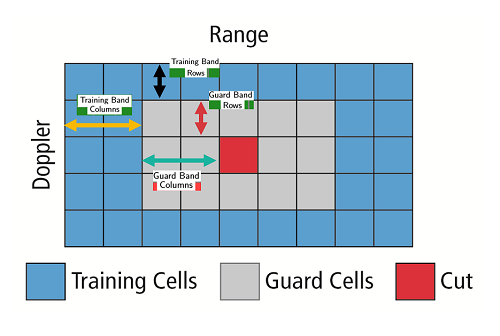

- 2D CA-CFAR Grid parameter : Variable

- Training band columns : Tr

- Training band rows : Td

- Guard band columns : Gr

- Guard band rows : Gd

- CUT cells range : [min_r : max_r]

- CUT cells doppler : [min_d : max_d]

training_area = (TGCells_range+1)*(TGCells_doppler+1);
guard_area = (2*Gr+1)*(2*Gd+1);

min_r = (Tr+Gr)+1;
max_r = (Nr/2)-(Gr+Tr);
min_d = (Td+Gd)+1;
max_d = (Nd)-(Gd+Td);
RDM_CFAR = zeros(size(RDM));

for r = min_r:max_r
    for d = min_d:max_d
        
        %For every iteration sum the signal level within all the training cells.
        %To sum convert the value from logarithmic to linear using db2pow function.

## Sum signal level within all the training cells

- Extract signal level values within the area inside guard cells (Guard cells + CUT)

- Extract signal level values within the area inside training cells (Training + sGuard cells + CUT)

- Sum all values belonging to each area after converting to linear scale using db2pow

- To calculate sum signal level in training cells only: Subtract sum of values inside the grey rectangle from sum of values inside the blue rectange

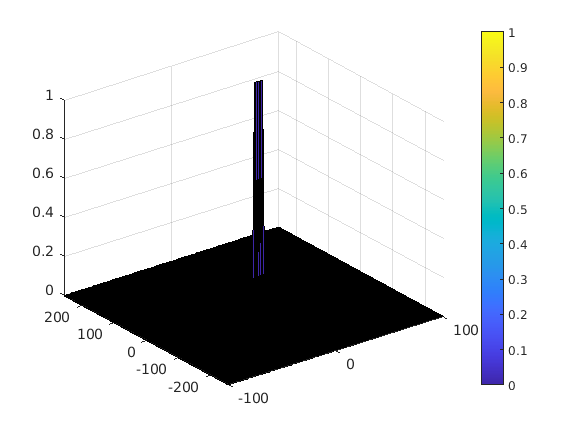

        %sum power level of guard area
        p_guard_area = sum(db2pow(RDM(r-Gr:r+Gr,d-Gd:d+Gd)),'all');
        %sum power level of training area

        p_train_area = sum(db2pow(RDM(r-(TGCells_range/2):r+(TGCells_range/2),d-(TGCells_doppler/2):d+(TGCells_doppler/2))),'all');
        %sum of power levels at training cells
        power_training = p_train_area - p_guard_area;

## Calculate average by dividing sum of signal level in training cells on number of training cells

        %Average the summed values for all of the training cells used
        avg_power_training = power_training / (training_area-guard_area);

## Establish threshold level by converting Average training level to dB and adding an offset

        %After averaging convert it back to logarithimic using pow2db.
        %Further add the offset to it to determine the threshold.
        %db is a logarithmic ratio of powers
        threshold = pow2db(avg_power_training) * offset;

## Compare CUT level to Threshold

- Store comparison outcome in a new array of the same size as RDM

- Set 1 when CUT level is above threshold

- Set 0 Otherwise

        %Next, compare the signal under CUT with this threshold.
        %If the CUT level > threshold assign it a value of 1
        if (RDM(r,d) > threshold)
            RDM_CFAR(r,d) = 1;
        %Else equate it to 0.
        else
            RDM_CFAR(r,d) = 0;
        end
    end
end

% *%TODO* :
% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 
 
%Done by initializing RDM_CFAR to zeros

% *%TODO* :
%display the CFAR output using the Surf function like we did for Range

## Doppler Response output.

figure,surf(doppler_axis,range_axis,RDM_CFAR);
colorbar;